# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 5.6.4 Minimum Entropy

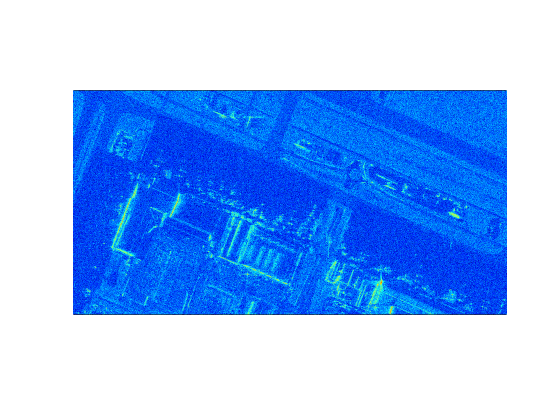

[file,path] = uigetfile('*.h5');
filename = fullfile(path,file);

% Form complex image data
s_i = h5read(filename, '/s_i');
s_q = h5read(filename, '/s_q');
s = double(s_i) + 1j * double(s_q);

clear s_i s_q

% Set the dynamic range for the image
dynamic_range = 65;

% Data size
[nx, ny] = size(s);
ratio = ny/nx;

% Pixel offset from image center
offset_x = 1000;
offset_y = 3000;

xc = round(nx/2) - offset_x;
yc = round(ny/2) - offset_y;

% Specify a span / or fixed aspect
xs = 1000;
ys = 2000;
% ys = round(ratio * xs);

% For full image
% xs = nx/2-1;
% ys = ny/2-1;

% Calculate the image indices
index_x = xc-xs:xc+xs;
index_y = yc-ys:yc+ys;

% For specifying a particular location and size in the image
% index_x = 1:19310;
% index_y = 1:5000;

xs = round( (index_x(end) - index_x(1)) / 2);
ys = round( (index_y(end) - index_y(1)) / 2);

% Extract desired image area
s = s(index_x, index_y);  [nx, ny] = size(s);

% Calculate the phase error
t = linspace(-1.00, 1.50, nx);
phi = 10*(t.^2 + cos(t.^4).^2);
phi = phi - phi(1);

% Calculate the phase error term
phase_term = exp(1j * phi') * ones(1, ny);
fmn = fftshift(fft(s), 1);
g = ifft(phase_term .* fmn);

% Save the corrupted image
gc = g;

% for i = 1:iterations

% Calculate the terms
term1 = conj(fmn) / nx;
term2 = (1 + log2(abs(g).^2)) .* g;
term3 = fft(term2);


a = 0;
for n = 1:ny
    a = a + term1(:,n) .* term3(:,n);
end

% Unwrap the phase
phi_c = unwrap(angle(a));
phase_term = exp(-1j * phi_c) * ones(1, ny);
fmn = fft(g);
g = ifft(phase_term .* fmn);


% Original image
figure;
pcolor(db(s)'); shading flat;
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])

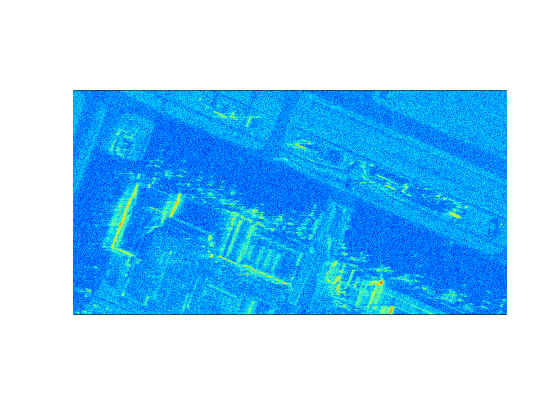


% Corrupted image
figure;
pcolor(db(gc)'); shading flat;
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0])
axis square
pbaspect([ratio * xs / ys 1 1])

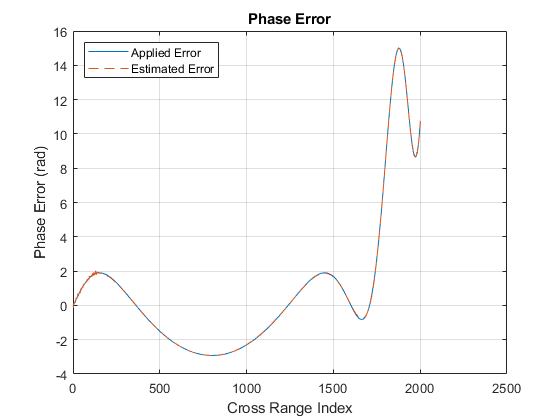


% Compare phase error
figure;
plot(phi);
hold on; plot(phi_c, '--');
title('Phase Error')
xlabel('Cross Range Index')
ylabel('Phase Error (rad)')
legend('Applied Error', 'Estimated Error', 'location', 'northwest')
grid on

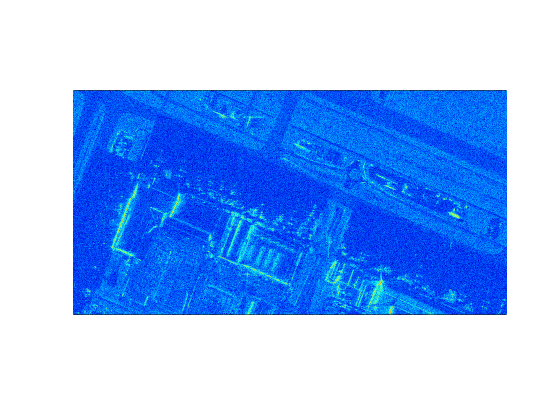


% Corrected image
figure;
pcolor(db(g)'); shading flat;
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])